# CVRP Valerio Firmano, Margherita Soro, Cecilia Cardellino

## Data downloaded from CVRPLIB [http://vrp.atd-lab.inf.puc-rio.br/index.php/en/](http://vrp.atd-lab.inf.puc-rio.br/index.php/en/)


$$x\_coord,y\_coord \rightarrow \text{Coordinate clienti}
\\k = 1...numMacchine \rightarrow \text{Mezzi disponibili}
\\demand_i\rightarrow \text{Domanda clienti}\\
capacity\rightarrow \text{Capacità del mezzo}\\
cost_{i, j}\rightarrow \text{Distanza tra clienti}\\
tot\_cost\_opt\rightarrow \text{Miglior soluzione in letteratura}\\
$$


#### La funzione *initialize *legge i dati direttamente dai CSV nella cartella Data e setta le variabili iniziali

%VARIABLE INITIALIZATION DIRECT FROM CSV FILES
clear all;
[x_coord,y_coord,depo,d,distance,cost,v,capacity,numMacchine,tot_cost_opt]=...
    initialize('Data/E-n51-k5.csv');

numCostumers=size(x_coord,1);

## Clustering

### Algoritmo di di Fisher,Jaikumar

Individuiamo le posizioni dei semi a priori

La posizione del seme $\sigma_{k+1} \;$si trova risolvendo: 


$$\max_i\min\{c_{i0},c_{i,\sigma_1},c_{i,\sigma_2},...,c_{i,\sigma_k}\}$$


dove $c_{i\sigma_k}$ è la distanza del punto i dal seme k.

%TROVO POSIZIONI DEI SEMI
seed_pos=zeros(1,numMacchine);
[~,seed_pos(1)]=max(distance(1,1:end));
for i=2:length(seed_pos)
    distance_support=ones(size(distance))*inf;
    distance_support([1,seed_pos(seed_pos~=0)],setdiff(1:end,[1,seed_pos(seed_pos~=0)]))...
        =distance([1,seed_pos(seed_pos~=0)],setdiff(1:end,[1,seed_pos(seed_pos~=0)]));
    support_vector=min(distance_support);
    support_vector(support_vector==inf)=0;
    [~,seed_pos(i)]=max(support_vector);
end

seed_pos=seed_pos-1; %shifto le posizioni di 1 considerando il deposito come zero

## Problema di assegnamento generalizzato una volta trovati i semi dei cluster

### Variabili decisionali


$$$$y_{i, k}= 0,1 \rightarrow \text{Valore binario che indica se il cliente i è assegnato al mezzo k}$$$$


### Variabili del problema


$$	$c_{i, k}= c_{0,1}+c_{i,\sigma_k}-c_{0,\sigma_k} \rightarrow \text{Costo di tipo "Extra Mileage" di inserire \textit{i} nel cammino \textit{k}}\\
	d_i\rightarrow \text{Domanda del cliente \textit{i}}$$$


### Vincoli


$$$\sum_{k=1}^{m}y_{ik}=1\ \ \ \ \forall i=1,...,n\\
	\sum_{i=1}^{n}d_iy_{ik}\le R\ \ \ \ \forall k=1,...,m\\
	y_{ik}\in\{0,1\}$$$


### Funzione obbiettivo


$$$\sum_{k=1}^{m}\sum_{i=1}^{n}c_{ik}y_{ik}$$$


%RISOLVO IL PROBLEMA GAP DI FISHER JAKUMAR
tic
[sol_FJ,GAPprob_FJ]=clustering_2(numCostumers,numMacchine,capacity,d,seed_pos,distance)

Solving problem using intlinprog.
LP:                Optimal objective value is 3286.424081.                                          

Cut Generation:    Applied 19 cover cuts, 8 mir cuts,                                               
                   and 2 strong CG cuts.                                                            
                   Lower bound is 3360.000000.                                                      

Heuristics:        Found 1 solution using rounding.                                                 
                   Upper bound is 3517.000000.                                                      
                   Relative gap is 4.46%.                                                          

Heuristics:        Found 1 solution using total rounding.                                           
                   Upper bound is 3360.000000.                                                      
                   Relative gap is 0.00%.              

sol_FJ = struct with fields:
    y_2: [75×5 double]


GAPprob_FJ =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 2 OptimizationConstraints

  See problem formulation with show.


toc

Elapsed time is 1.607813 seconds.


## Soluzione del problema TSP all'interno dei cluster individuati

Nella funzione *solver *sono implementati un metodo costruttivo basato su **Extra mileage **e un metodo **2-opt, **che prende la soluzione costruttiva come punto di partenza, per risolvere il problema TSP in ogni cluster. La presenza di una soluzione *feasible *ci è garantita dal fatto che i vincoli di capacità sono già stati considerati nel GAP problem di Clustering.

[T_matrix_x_FJ,T_matrix_y_FJ,T_cost_vec_FJ,tot_cost_FJ]=solver(sol_FJ.y_2,numMacchine,numCostumers,x_coord,y_coord);

## Plot dei risultati

%Costo totale con il nostro algoritmo
tot_cost_FJ

tot_cost_FJ = 699

%Costo ottimo in letteratura
tot_cost_opt

tot_cost_opt = 627

%Errore
percentuale_errore=(tot_cost_FJ-tot_cost_opt)/tot_cost_opt*100

percentuale_errore = 11.4833

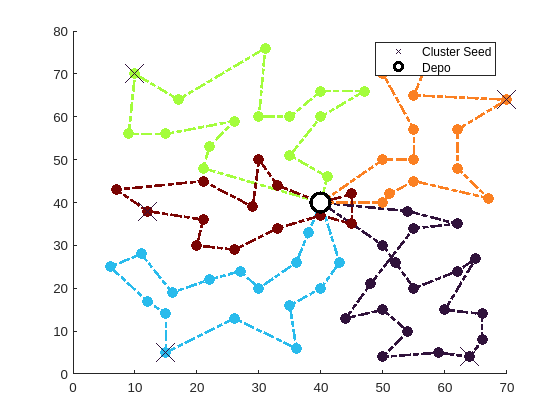


clf(figure,'reset')
figure

color = turbo(numMacchine);
colororder(color)
hold on
for ii=1:numMacchine
    %scatter(tabTx(:,ii),tabTy(:,ii),100,'filled')
    p=plot(nonzeros(T_matrix_x_FJ(ii,:)),nonzeros(T_matrix_y_FJ(ii,:)),'-.o','LineWidth',2,'MarkerSize',...
        6,'MarkerEdgeColor',color(ii,:),'MarkerFaceColor',color(ii,:));
    %plot(nonzeros(tabTx (:,ii)),nonzeros(tabTy(:,ii)),100,'filled')
    p.Annotation.LegendInformation.IconDisplayStyle = 'off';
end
scatter(x_coord(seed_pos+1),y_coord(seed_pos+1),400,'marker','x','DisplayName','Cluster Seed')
scatter(depo(1),depo(2),200,'MarkerEdgeColor','black','MarkerFaceColor','white','LineWidth',2.5,...
    'marker','o','DisplayName','Depo')

legend
hold off

## Problema di assegnamento generalizzato una volta trovati i semi dei cluster

### Variabili decisionali


$$$$y_{i, j}= 0,1 \rightarrow \text{Valore binario che indica se il cliente i è assegnato al cluster di cui j è seme}\\
z_{j}= 0,1 \rightarrow \text{Valore binario che indica se il cliente j è selezionato come seme del cluster}$$$$


### Variabili del problema


$$	$g_{i, j}= c_{0,i}+c_{i,j}-c_{0,j} \rightarrow \text{Costo di tipo "Extra Mileage" }\\
v_j= 2c_{0,j} \rightarrow \text{Costo della selezione di j come seme}\\
	d_i\rightarrow \text{Domanda del cliente \textit{i}}$$$


### Vincoli


$$$\sum_{j=1}^{m}y_{ij}=1\ \ \ \ \forall i=1,...,n\\
	\sum_{i=1}^{n}d_iy_{ij}\le R\ \ \ \ \forall k=1,...,m\\
\sum_{i=1}^{n}z_{j}= m\\
y_{ij} \le z_j \ \ \ \ \forall i,j=1,..,n\\
	y_{ij},z_j\in\{0,1\}$$$


### Funzione obbiettivo


$$$\sum_{i=1}^{n}\sum_{j=1}^{n}g_{ij}y_{ij}+\sum_{j=1}^{n}v_jz_j$$$


### L'algoritmo di Bramel Simchi-Levi funziona solo per un basso numero di clienti data la sua complessità

Funziona bene per i casi con numCostumers <=50

%CLUSTERING SOLVING A GAP PROBLEM WITH NO-FIXED SEEDS POSITIONS (BRAMEL,
%SIMCHI-LEVI)
tic
[sol_BS,GAPprob_BS]=clustering(numCostumers,numMacchine,capacity,d,cost,v);

Solving problem using intlinprog.
LP:                Optimal objective value is 6512.191683.                                          

Cut Generation:    Applied 10 Gomory cuts, 7 cover cuts,                                            
                   1 zero-half cut, and 1 strong CG cut.                                            
                   Lower bound is 6587.000000.                                                      

Heuristics:        Found 1 solution using diving.                                                   
                   Upper bound is 10548.000000.                                                     
                   Relative gap is 37.55%.                                                         

Cut Generation:    Applied 10 Gomory cuts,                                                          
                   and 1 zero-half cut.                                                             
                   Lower bound is 6594.000000.         

toc

Elapsed time is 82.953846 seconds.


% %CLUSTERING SOLVING A GAP PROBLEM WITH NO-FIXED SEEDS POSITIONS (BRAMEL,
% %SIMCHI-LEVI)
% z0=zeros(numCostumers-1,1);
% z0(seed_pos)=1;
% y0=zeros(numCostumers-1);
% y0(:,seed_pos)=sol_FJ.y_2;
% 
% [sol_BS,GAPprob_BS]=clustering_prova(numCostumers,numMacchine,capacity,d,cost,v,y0,z0);

[T_matrix_x_BS,T_matrix_y_BS,T_cost_vec_BS,tot_cost_BS]=solver (sol_BS.y,numMacchine,numCostumers,x_coord,y_coord);

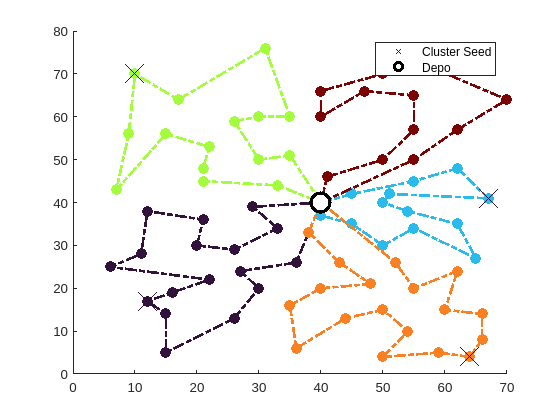

clf(figure,'reset')
figure

color = turbo(numMacchine);
colororder(color)
hold on
for ii=1:numMacchine
    %scatter(tabTx(:,ii),tabTy(:,ii),100,'filled')
    p=plot(nonzeros(T_matrix_x_BS(ii,:)),nonzeros(T_matrix_y_BS(ii,:)),'-.o','LineWidth',2,'MarkerSize',...
        6,'MarkerEdgeColor',color(ii,:),'MarkerFaceColor',color(ii,:));
    %plot(nonzeros(tabTx (:,ii)),nonzeros(tabTy(:,ii)),100,'filled')
    p.Annotation.LegendInformation.IconDisplayStyle = 'off';
end
scatter(x_coord(find(sol_BS.z)+1),y_coord(find(sol_BS.z)+1),400,'marker','x','DisplayName','Cluster Seed')
scatter(depo(1),depo(2),200,'MarkerEdgeColor','black','MarkerFaceColor','white','LineWidth',2.5,...
    'marker','o','DisplayName','Depo')

legend
hold off